%rosshutdown
rosinit('10.0.108.89')

Initializing global node /matlab_global_node_31941 with NodeURI http://10.0.109.0:54619/ and MasterURI http://10.0.108.89:11311.


%rosshutdown

%%Init Setup
rostopic list

/clicked_point                                                                  
/diagnostics                                                                    
/rosout                                                                         
/rosout_agg                                                                     
/tf                                                                             
/tf_static                                                                      
/zedm/joint_states                                                              
/zedm/zed_node/confidence/confidence_map                                        
/zedm/zed_node/depth/camera_info                                                
/zedm/zed_node/depth/depth_registered                                           
/zedm/zed_node/depth/depth_registered/compressed                                
/zedm/zed_node/depth/depth_registered/compressed/parameter_descriptions         
/zedm/zed_node/depth/depth_r

dispFlag=1;
useRectified=0;
useSystemStereo=1;

if(useRectified)
    imL_sub=rossubscriber('/zedm/zed_node/left/image_rect_color');
    imR_sub=rossubscriber('/zedm/zed_node/right/image_rect_color');
    if(useSystemStereo)
        imS_sub=rossubscriber('/zedm/zed_node/stereo/image_rect_color');
    end
else
    imL_sub=rossubscriber('/zedm/zed_node/left_raw/image_raw_color');
    imR_sub=rossubscriber('/zedm/zed_node/right_raw/image_raw_color');
    if(useSystemStereo)
        imS_sub=rossubscriber('/zedm/zed_node/stereo_raw/image_raw_color');
    end
end

nav_pub=rospublisher('/vision_team/command','std_msgs/String');
depth_pub=rospublisher('/vision_team/depth','std_msgs/String');
[target_pub,target_msg]=rospublisher('/vision_team/target_pos', 'geometry_msgs/Point');
pause(1);

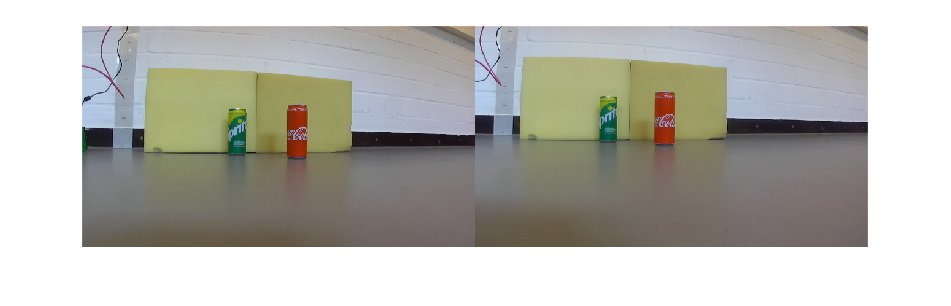

imL_msg= receive(imL_sub);
imR_msg= receive(imR_sub);
imS_msg= receive(imS_sub);
imL=readImage(imL_msg);
imR=readImage(imR_msg);
imS=readImage(imS_msg);
imshow([imS]);

load zedParameters
show = dispFlag;

im_size = size(imS);
imLeft = imS(:,1:im_size(2)/2,:);
imRight = imS(:,im_size(2)/2+1:im_size(2),:);

[imLeftRect, imRightRect,reprojectionMatrix] = rectifyStereoImages(imLeft, imRight, stereoParams);

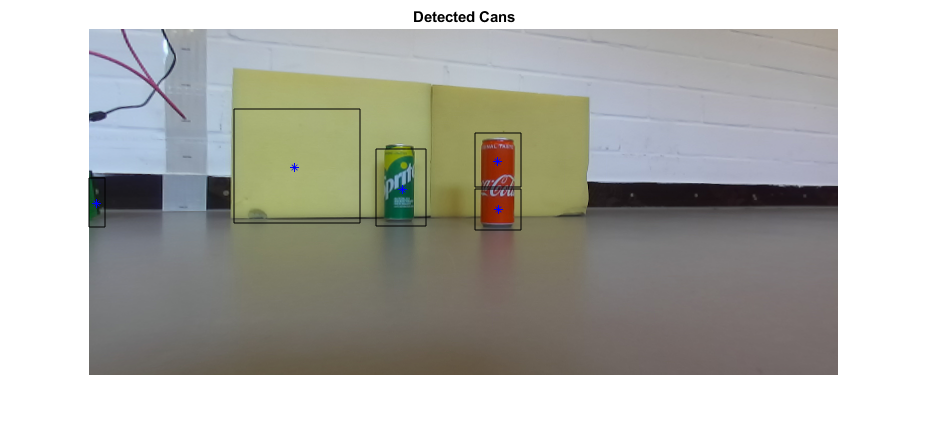

[bbox_rec, certainty]= colorSegmentation(imLeftRect,dispFlag);

if(dispFlag)
    figure
    imshow(stereoAnaglyph(imLeftRect, imRightRect))

    title('Rectified Images')
end

P_robot = 3×1 single column vector
    0.0458
    0.8684
   -0.0202


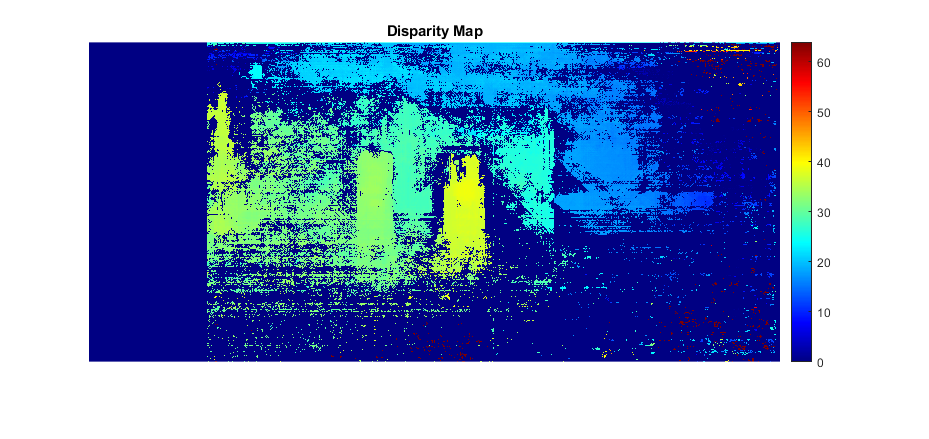

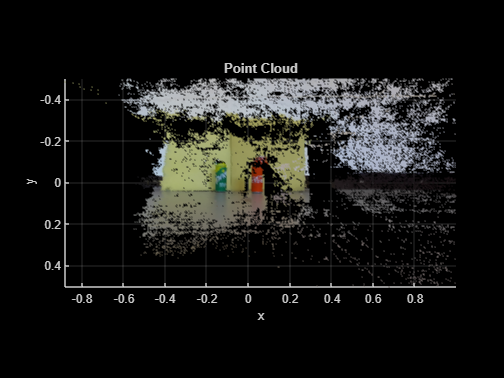

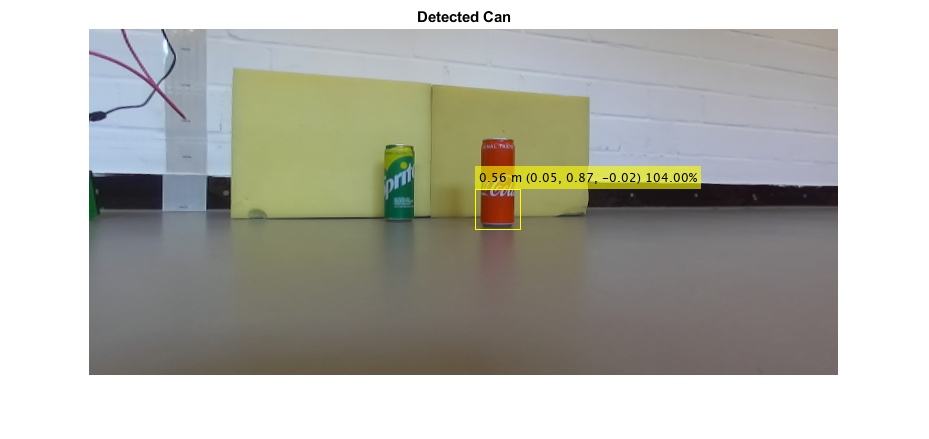

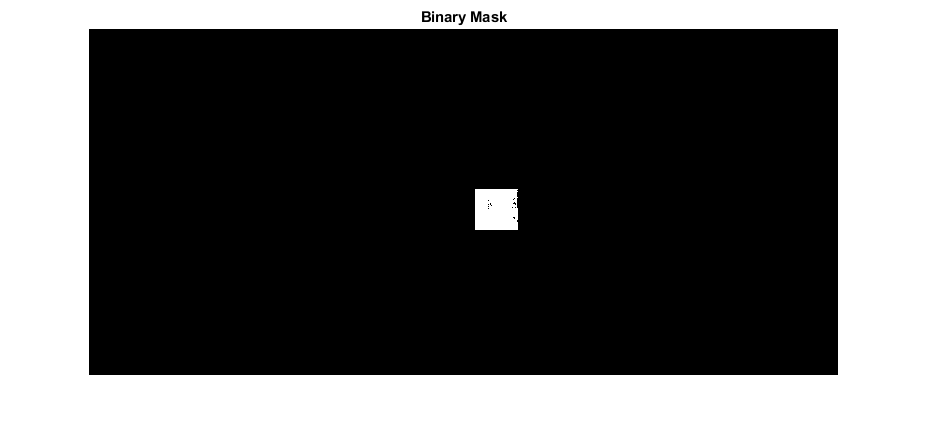

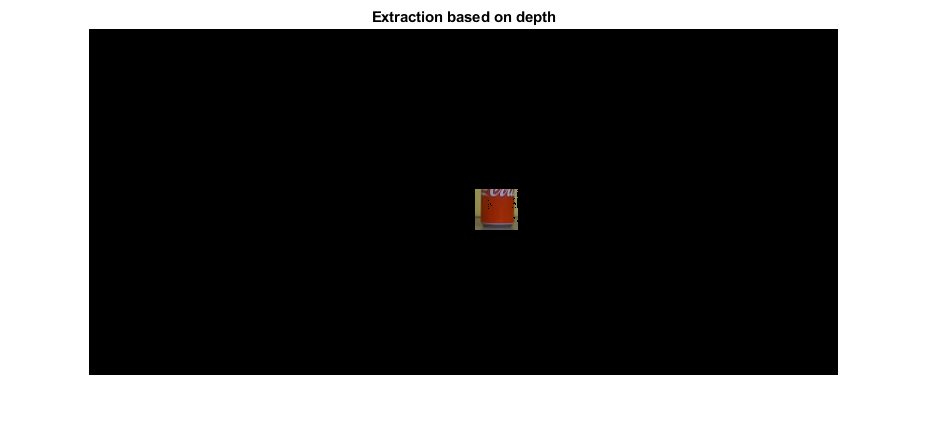

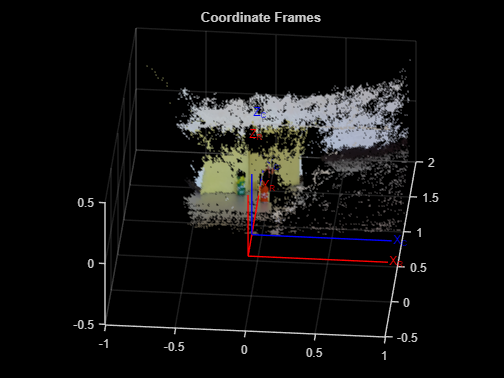

P_robot = depthEstCans(imLeftRect, imRightRect, reprojectionMatrix, bbox_rec, certainty, show);

xr = P_robot(1)

xr = single
0.0458

yr = P_robot(2)

yr = single
0.5624

zr = P_robot(3)

zr = single
-0.0202

%while 1
    [pub,msg] = rospublisher('target_position','geometry_msgs/Point');
    msg.X = xr

Unrecognized function or variable 'xr'.

    msg.Y = yr
    msg.Z = zr
    send(pub,msg);
%end